# Contest Report

% Read in the list of all solvers
solvers = readtimetable("allSolvers.csv");

% Get rid of bad entries
% The score may be infinite or negative. Neither is a good state.
ix = isinf(solvers.score)|(solvers.result<0);
solvers(ix,:) = [];

Here is the list of all the solvers

solvers

solvers = 1x5 timetable
             t              result    computeTime    score      author                         commit                   
    ____________________    ______    ___________    _____    __________    ____________________________________________

    06-May-2024 21:30:44    8447.5     0.012358      42239    {'gulley'}    {'af3705fb448b7d5caa7c3178305b69702954c9b7'}


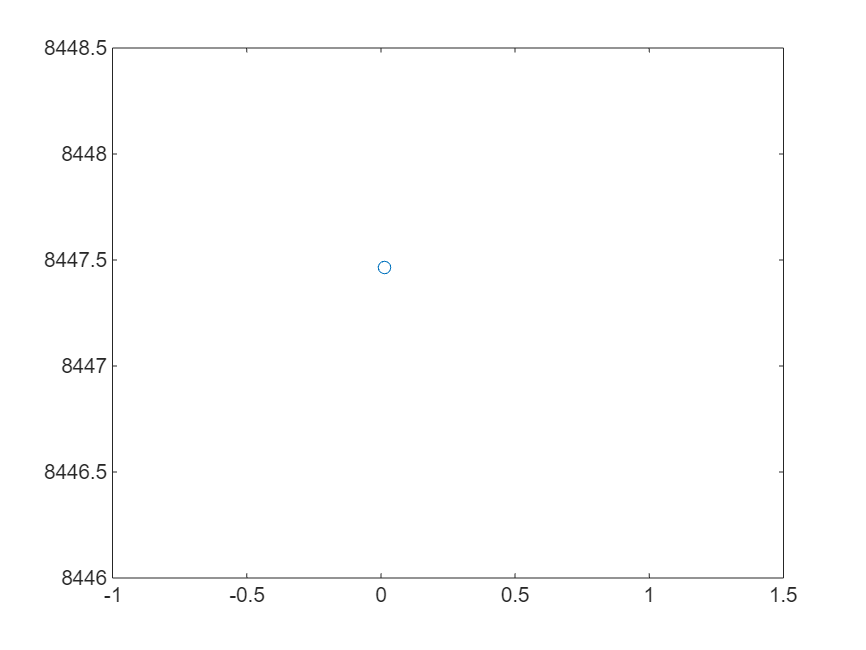

plot(solvers.computeTime,solvers.result,"-o")

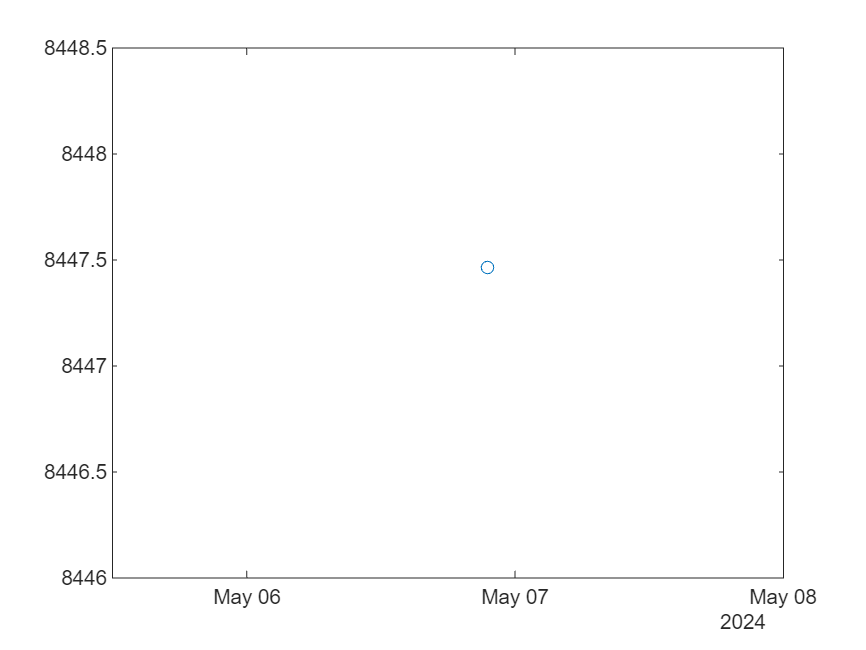

plot(solvers.t,solvers.result,"-o")